首先给定等待计算方程的形式:


$$\left\lbrace \begin{array}{ll}
-\Delta u=-6\left(x+y\right), & \left(x,y\right)\in \left(0,1\right)\times \left(0,1\right),\\
u\left(x,0\right)=x^3 ,u\left(x,1\right)=1+x^3 , & x\in \left\lbrack 0,1\right\rbrack ,\\
u\left(0,y\right)=y^3 ,u\left(1,y\right)=1+y^3 , & y\in \left\lbrack 0,1\right\rbrack \ldotp 
\end{array}\right.\left(1\right)$$


这里方程的唯一精确解为$u\left(x,y\right)=x^3 +y^3 \ldotp$

将方程用差分格式近似,近似的离散方程组为


$$\left\lbrace \begin{array}{ll}
-\delta_x^2 u_{j_1 ,j_2 } -\delta_y^2 u_{j_1 ,j_2 } =f\left(x_{j_1 } ,y_{j_2 } \right), & j_1 =1:J_1 ,j_2 =1:J_2 \\
u\left(x_{j_1 } ,0\right)=\varphi_1 \left(x_{j_1 } \right),u\left(x_{j_1 } ,1\right)=\varphi_2 \left(x_{j_1 } \right), & j_1 =0:J_1 ,\\
u\left(0,y_{j_2 } \right)=\psi_1 \left(y_{j_2 } \right),u\left(1,y_{j_2 } \right)=\psi_2 \left(y_{j_2 } \right)\ldotp  & j_2 =0:J_2 \ldotp 
\end{array}\right.\left(2\right)$$


有了离散形式的方程组,现在就可以来求解$(1)$的数值解了.

首先定义一些基本参数.

clear
%f是非齐次项
f=@(x,y)(-6*(x+y));
%边界条件函数
varphi_1=@(x)(x.^3);
varphi_2=@(x)(1+x.^3);
psi_1=@(y)(y.^3);
psi_2=@(y)(1+y.^3);
%u_ES是精确解函数
u_ES=@(x,y)(x.^3+y.^3);
%迭代步数定义
J1=50;
J2=50;
%计算区间端点定义
a1=0;
b1=1;
a2=0;
b2=1;
L1=(b1-a1);
L2=(b2-a2);
%均匀步长h1,h2定义
h1=(L1/J1);
h2=(L2/J2);

然后定义数值解和精确解的储存矩阵

%u是数值解储存矩阵,u_ESM是精确解储存矩阵
u=zeros(J1+1,J2+1);
u_ESM=zeros(J1+1,J2+1);

开始初值赋予

j_1=@(x)(x+1);
j_2=@(x)(x+1);
for j1_c=0:J1
    j1=j1_c+1;
    u(j1,j_2(0))=varphi_1(j1_c*h1);
    u(j1,j_2(J2))=varphi_2(j1_c*h1);
end
for j2_c=0:J2
    j2=j2_c+1;
    u(j_1(0),j2)=psi_1(j2_c*h2);
    u(j_1(J1),j2)=psi_2(j2_c*h2);
end

开始用$(2)$进行迭代计算.

注意,$(2)$式可以使用Jacobi迭代计算,计算的收敛性当然有保证.

alpha=2*(h1^(-2)+h2^(-2));
beta=h1^(-2);
gamma=h2^(-2);
% Iterate over the grid points and compute the numerical solution
for k = 1:10000
    for j1_c = 1:J1-1
        j1=j1_c+1;
        for j2_c = 1:J2-1
            j2=j2_c+1;
            u(j1,j2)=alpha^(-1)*(f(j1_c*h1,j2_c*h2)...
                +beta*u(j1-1,j2)+beta*u(j1+1,j2) ...
                +gamma*u(j1,j2-1)+gamma*u(j1,j2+1));
        end
    end
end

% Compute the exact solution on the grid
for j1 = 1:J1+1
    for j2 = 1:J2+1
        u_ESM(j1,j2) = u_ES((j1-1)*h1,(j2-1)*h2);
    end
end

% Compare the numerical and exact solutions
disp(max(max(abs(u - u_ESM))));

   3.5527e-15



绘图

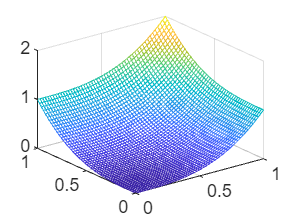

[X,Y] = meshgrid(a1:h1:b1,a2:h2:b2);
mesh(X,Y,u)